## Zadanie 4   Optymalizacja regulatora od stanu systemu LQR

Optymalizacja regulatora od stanu systemu LQR (Teoria sterowania), przy funkcjach kosztu na stan i sterowanie.

Optymalne rozwiązanie otrzymuje się poprzez rozwiązanie macierzowego równania różniczkowego Riccatiego, dla zerowych warunków początkowych problem upraszcza się do algebraicznego równania Riccatiego funkcja "lqr" w Matlab.

Przykład numerycznego rozwiązania problemu nałożenia funkcji kosztu na stan i sterowanie przedstawiono w temacie optymalizacji wielokryterialnej Ćwicz. lab. 10 / Optymalizacja wielokryterialna / Przykład 10.1. optymalizacji wielokryterialnej regulatora od stanu (wraz z korektą). (optymalne kryterium stanu i sterowania na trajektoriach systemu).

Poniżej podano przykłady optymalizacji regulatora LQR, czasowo optymalnej (nie na trajektoriach systemu, bardzo duża wartość współczynników regulatora, gwałtowne uderzenie sterowania) oraz wersja (2) poprzez minimalizację błędu względem optymalizacji na trajektoriach systemu uzyskanych z funkcji lqr.

Przykład:

clear
G1=tf([1],[1 3 4 2]) % System

G1 =
 
            1
  ---------------------
  s^3 + 3 s^2 + 4 s + 2
 
Continuous-time transfer function.



[A,B,C,D] = tf2ss([G1.Numerator{1, 1}],[G1.Denominator{1, 1}])

A =     -3    -4    -2
     1     0     0
     0     1     0


B =      1
     0
     0


C =      0     0     1


D = 0

sys = ss(A,B,C,D)

sys =
 
  A = 
       x1  x2  x3
   x1  -3  -4  -2
   x2   1   0   0
   x3   0   1   0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
 
  C = 
       x1  x2  x3
   y1   0   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



%[K,S,e] = lqr(SYS,Q,R,N)
R=1

R = 1

Q=ones(length(G1.Denominator{1, 1})-1)

Q =      1     1     1
     1     1     1
     1     1     1


N=0

N = 0

[K,S,e] = lqr(sys,Q,R,N)

K =     0.2152    0.1688    0.2361


S =     0.2152    0.1688    0.2361
    0.1688    0.1675    0.1894
    0.2361    0.1894    0.3217


e =   -0.9287 + 0.8856i
  -0.9287 - 0.8856i
  -1.3578 + 0.0000i


K_lqr=K

K_lqr =     0.2152    0.1688    0.2361


%Uklad zamknięty z regulatorem LQR od stanu
C_loop=eye(length(G1.Denominator{1, 1})-1)

C_loop =      1     0     0
     0     1     0
     0     0     1


sys_loop = ss(A-B*K,B,C_loop,0) % K reg LQR optym na trajekt stanu dla zerowych war poczatkowych

sys_loop =
 
  A = 
           x1      x2      x3
   x1  -3.215  -4.169  -2.236
   x2       1       0       0
   x3       0       1       0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
 
  C = 
       x1  x2  x3
   y1   1   0   0
   y2   0   1   0
   y3   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
 
Continuous-time state-space model.



A_lqr=[-3.215 -4.169 -2.236;1 0 0;0 1 0]

A_lqr =    -3.2150   -4.1690   -2.2360
    1.0000         0         0
         0    1.0000         0


B_lqr=[1;0;0]

B_lqr =      1
     0
     0


C_lqr=[1 0 0;0 1 0;0 0 1]

C_lqr =      1     0     0
     0     1     0
     0     0     1


t=0:0.01:10;
[y_lqr] = step(sys_loop,t);
y_lqr=y_lqr(:,1)

y_lqr =          0
    0.0098
    0.0194
    0.0286
    0.0375
    0.0461
    0.0544
    0.0625
    0.0702
    0.0777


[z,p,k_sys_loop] = ss2zp(sys_loop.A,sys_loop.B,sys_loop.C,sys_loop.D)

z =      0     0   Inf
     0   Inf   Inf


p =   -1.3578 + 0.0000i
  -0.9287 + 0.8856i
  -0.9287 - 0.8856i


k_sys_loop =      1
     1
     1


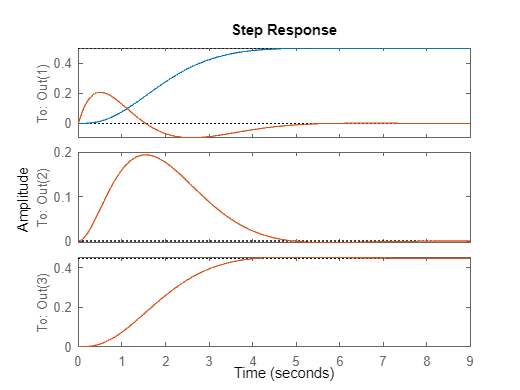

step(sys,sys_loop)

x0 = [0,0,0]; %
fun = @ident;
options = optimset('Display','iter','PlotFcns',@optimplotfval);
[x,fval,exitflag] = fminsearch(fun,x0,options)

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          1.71517         
     1            4          1.71145         initial simplex
     2            5          1.71145         reflect
     3            7          1.70806         expand
     4            9          1.70246         expand
     5           11          1.69745         expand
     6           13          1.68515         expand
     7           15          1.66909         expand
     8           17          1.64707         expand
     9           19          1.60731         expand
    10           21          1.55499         expand
    11           23          1.47532         expand
    12           25          1.35379         expand
    13           27          1.19121         expand
    14           29         0.961109         expand
    15           31         0.670568         expand
    16           33         0.360155         expand
    17           35          0.14592         expand
   

x =     0.2150    0.1690    0.2360


fval = 2.3167e-09

exitflag = 1

sys_loop = ss(A-B*K,B,C_loop,0);
G1=tf([1],[1 3 4 2]); % System
K_num = [x(1),x(2),x(3)]; % LQR Controller
sys_loop_num = ss(A-B*K,B,C_loop,0)

sys_loop_num =
 
  A = 
           x1      x2      x3
   x1  -3.215  -4.169  -2.236
   x2       1       0       0
   x3       0       1       0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
 
  C = 
       x1  x2  x3
   y1   1   0   0
   y2   0   1   0
   y3   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
 
Continuous-time state-space model.



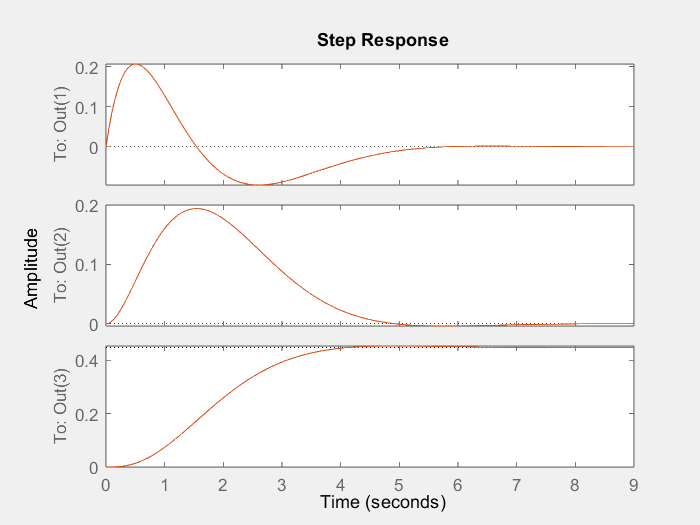

%step(G1);
step(sys_loop,sys_loop_num);

[z,p,k_sys_loop] = ss2zp(sys_loop.A,sys_loop.B,sys_loop.C,sys_loop.D)

z =      0     0   Inf
     0   Inf   Inf


p =   -1.3578 + 0.0000i
  -0.9287 + 0.8856i
  -0.9287 - 0.8856i


k_sys_loop =      1
     1
     1


K_lqr

K_lqr =     0.2152    0.1688    0.2361


K_num

K_num =     0.2150    0.1690    0.2360


function blad = ident(x)
A_lqr=[-3.215 -4.169 -2.236;1 0 0;0 1 0];
B_lqr=[1;0;0];
C_lqr=[1 0 0;0 1 0;0 0 1];
sys_lqr = ss(A_lqr,B_lqr,C_lqr,0);
G1=tf([1],[1 3 4 2]); % System
[A,B,C,D] = tf2ss([G1.Numerator{1, 1}],[G1.Denominator{1, 1}]);
C_loop=eye(length(G1.Denominator{1, 1})-1);
K = [x(1),x(2),x(3)]; % LQR Controller
A-B*K;
sys_loop = ss(A-B*K,B,C_loop,0);
t=0:0.01:10;
[y] = step(sys_loop,t);
[y_lqr] = step(sys_lqr,t);
% !!! WAZNE !!!
% do przesledzenia poprzez alternatywne załączanie funkcji celu wersja (1) lub wersja (2)
% (1)
% blad= sum(y(:,1).^2+y(:,2).^2+y(:,3).^2); % (1) minimalizacja trajektorii ukladu zamknietego sys_loop = ss(A-B*K,B,C_loop,0)
% minimalizacja trajektorii ukladu zamknietego sys_loop = ss(A-B*K,B,C_loop,0) optym numeryczna, bardzo duze wartosći wsp regulatora, gwałtowne
% uderzenie sterowania aby sprowadzić uklad do zera
% (2)
blad= sum((y(:,1)-y_lqr(:,1)).^2+(y(:,2)-y_lqr(:,2)).^2+(y(:,3)-y_lqr(:,3)).^2); % przyrównanie optymalizowanych numerycznie trajektorii
% ukladu zamknietego sys_loop = ss(A-B*K,B,C_loop,0) do trajektorii układu
% zamknietego optymalnego na trajektoriach systemu poprzez rozwiazanie rowania Riccatiego [K,S,e] = lqr(sys,Q,R,N)
end
